## Лабораторная работа № 2

`W ``- ВЕСОВОЙ КОЭФФИЦИЕНТ`

W = 3

W =      3

`P - коэффициент смещения`

p = -7;
x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


`Формула прямой, разделяющей координатную плоскость на части `

y = W .* x + p

y =     -4    -1     2     5     8    11    14    17    20    23


`Построим график функции y = 3x - 7`

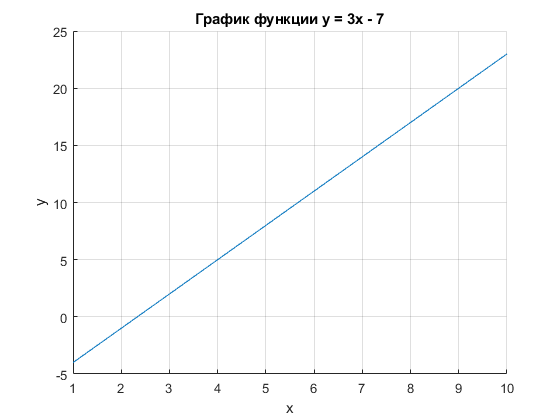

plot(x,y),grid on,box off,title('График функции y = 3x - 7'),xlabel('x'),ylabel('y');

`Выбрать 2 множества точек: 10 «черных» и 10 «белых» и выписать их координаты.`

`Координаты можно выбирать как целые, так и действительные (по желанию).`

`P – двумерный массив, содержит координаты выбранных точек по принципу: `

`первая строка – координаты х (абсциссы)`

`вторая строка – координаты y (ординаты)`

`Точки можно указывать в любом порядке, но помнить, где «черные», а где «белые».`

pointX_Black = [2, 3, 4, 5, 6, 7, 8, 9, 10, 1.5]

pointX_Black =    2.000000000000000   3.000000000000000   4.000000000000000   5.000000000000000   6.000000000000000   7.000000000000000   8.000000000000000   9.000000000000000  10.000000000000000   1.500000000000000


pointY_Black = [-6, -5, -4, -3, -2, -1, 0, 1, 2, -5]

pointY_Black =     -6    -5    -4    -3    -2    -1     0     1     2    -5


%               1  2  3  4  5  6  7  8  9   10
pointX_White = [2, 3, 4, 5, 6, 7, 8, 9, 10, 1]

pointX_White =      2     3     4     5     6     7     8     9    10     1


pointY_White = [0, 3, 6, 9, 12, 15, 18, 21, 24, -1]

pointY_White =      0     3     6     9    12    15    18    21    24    -1


P = [pointX_Black pointX_White; pointY_Black pointY_White]

P =    2.000000000000000   3.000000000000000   4.000000000000000   5.000000000000000   6.000000000000000   7.000000000000000   8.000000000000000   9.000000000000000  10.000000000000000   1.500000000000000   2.000000000000000   3.000000000000000   4.000000000000000   5.000000000000000   6.000000000000000   7.000000000000000   8.000000000000000   9.000000000000000  10.000000000000000   1.000000000000000
  -6.000000000000000  -5.000000000000000  -4.000000000000000  -3.000000000000000  -2.000000000000000  -1.000000000000000                   0   1.000000000000000   2.000000000000000  -5.000000000000000                   0   3.000000000000000   6.000000000000000   9.000000000000000  12.000000000000000  15.000000000000000  18.000000000000000  21.000000000000000  24.000000000000000  -1.000000000000000


`T – одномерный массив, определяет к какому множеству относятся точки. `

`Принято для точек, лежащих выше прямой («белых») указывать 1, а для точек ниже прямой («черных») – указывать 0.`` Количество элементов массива T равно количеству столбцов массива P и «цветовая принадлежность» указывается в том же порядке, что и координаты точек в массиве P`

T = [0 0 0 0 0 0 0 0 0 0 ...
	1 1 1 1 1 1 1 1 1 1]

T =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1


Добавим на график прямой  наши координаты и выделим цветом 

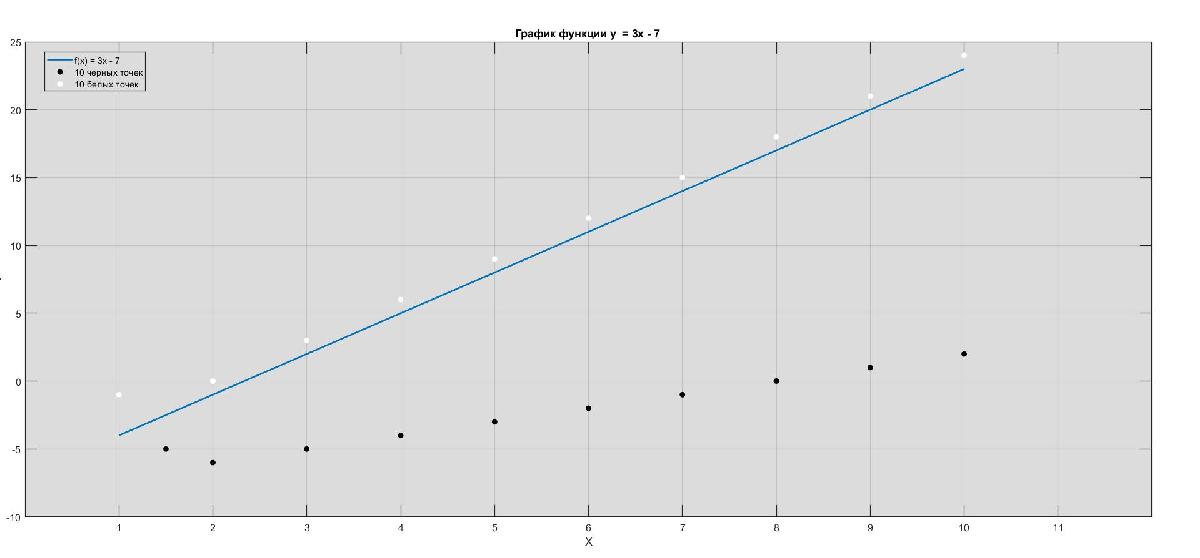

`Создать однослойный персептрон `

p_4 = newp(minmax(P),1)

p_4 =
    Neural Network
              name: 'Custom Neural Network'
          userdata: (your custom info)
    dimensions:
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
    connections:
       biasConnect: true
      inputConnect: true
      

p_4.adaptParam.passes = 10

p_4 =
    Neural Network
              name: 'Custom Neural Network'
          userdata: (your custom info)
    dimensions:
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
    connections:
       biasConnect: true
      inputConnect: true
      

Обучить персептрон на сформированных векторах P и T

p_4 = train(p_4,P,T)

p_4 =
    Neural Network
              name: 'Custom Neural Network'
          userdata: (your custom info)
    dimensions:
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
    connections:
       biasConnect: true
      inputConnect: true
      

Проверить правильность обучения персептрона на обучающей выборке 

% Y = sim(p_4,P)

Построение графика 

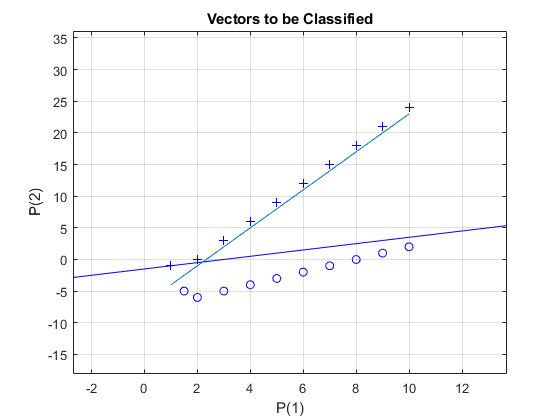

plotpv(P,T); hold on
plotpc(p_4.IW{1,1},p_4.b{1}); hold on
y = W*P(1,:) + p;
plot(P(1,:),y),grid;